# Mechanics of Materials Final Project

% Load I-Beam Data
[ibeam_data ibeam_text] = xlsread("Wide Flange Beams SI.xlsx");
[row col] = size(ibeam_data);
[row_text col_text] = size(ibeam_text);

% Create dataframe
ibeam_df(row) = struct('Designation', ' ', 'Area', 0, 'Depth', 0, 'WThick', 0, ...
    'FWidth', 0, 'FThick', 0, 'YY_I', 0, 'YY_S', 0, 'YY_r', 0, ...
    'ZZ_I', 0, 'ZZ_S', 0, 'ZZ_r', 0, 'I_final', 0);
ibeam_text(1:(row_text - row), :) = [];
for i = row:-1:1
    ibeam_df(i).Designation = ibeam_text(i, 1);
    ibeam_df(i).Area = ibeam_data(i,1)/(10^6);
    ibeam_df(i).Depth = ibeam_data(i,2)/(10^3);
    ibeam_df(i).WThick = ibeam_data(i,3)/(10^3);
    ibeam_df(i).FWidth = ibeam_data(i,4)/(10^3);
    ibeam_df(i).FThick = ibeam_data(i,5)/10^3;
    ibeam_df(i).YY_I = ibeam_data(i,6)/(10^6);
    ibeam_df(i).YY_S = ibeam_data(i,7)/(10^6);
    ibeam_df(i).YY_r = ibeam_data(i,8)/(10^3);
    ibeam_df(i).ZZ_I = ibeam_data(i,9)/(10^6);
    ibeam_df(i).ZZ_S = ibeam_data(i,10)/(10^6);
    ibeam_df(i).ZZ_r = ibeam_data(i,11)/(10^3);
    ibeam_df(i).I_final = 0;
end

% Define Constants
E = 200*10^9; % Young's Modulus A36 Steel (Pa)
sigma_y = 250*10^6; % Max Allowable Normal Stress A36 Steel (Pa)
tau_y = 150*10^6; % Max Allowable Shear Stress A36 Steel (Pa)
rho_water = 1000; % Density Water (kg/m^3)
rho_steel = 7800; % Density A36 Steel (kg/m^3)
g = 9.81; % Acceleration due to gravity (m/s^2)
alpha = 11.7*10^(-6); % Coefficient of Thermal Expansion A36 Steel (1/C)

% Define Dimensions, Cartesian Basis (m)
col_x = 0.1; 
col_y = 0.1;
col_z = 3;

gate_x = 4;
gate_z = 0.05;

ht_water_i = 2;
ht_water_f = 4;

temp = 5:40; % Exposed Temp Range (C)
temp_i = 25; % Initial Temp, all measurements taken here

% Variables to adjust
col_t = 0.001; % Thickness of Plates to add to columns (m)
%k = 0.5; % Fixed-Fixed Column
%k = 0.7; % Fixed-Pinned Column
k = 1.0; % Pinned-Pinned Column

% Calculate new I Values for Ibeams based on gate thickness
I_final = zeros(1,row);
for i = row:-1:1
    ibeam_df(i).I_final = calc_Ivalue(ibeam_df(i).FThick, ibeam_df(i).WThick, ibeam_df(i).Depth, ibeam_df(i).FWidth, gate_z);
end
ibeam_df

ibeam_df = 1×55 struct array with fields:
    Designation
    Area
    Depth
    WThick
    FWidth
    FThick
    YY_I
    YY_S
    YY_r
    ZZ_I
    ZZ_S
    ZZ_r
    I_final


% Calculate Initial & Final Weights of Water and Gate
% Over column
Wt_water_col_i = col_x*col_y*ht_water_i*rho_water*g;
Wt_steel_col = col_x*col_y*gate_z*rho_steel*g;
Wt_col_i = (Wt_water_col_i + Wt_steel_col)/1000; % kN
Wt_water_col_f = col_x*col_y*ht_water_f*rho_water*g;
Wt_col_f = (Wt_water_col_f + Wt_steel_col)/1000; % kN


## Thermal Analysis

% Column Initial Analysis
buckling_initial(temp(end)-temp(1)+1) = struct('Temp', 0, 'X', 0, 'Y', 0, 'Z', 0, 'Crit_Load', 0, 'Crit_Stress', 0, 'Max_All_Load', 0);
for i = length(temp):-1:1
    buckling_initial(i).Temp = temp(i);
    buckling_initial(i).X = thermal_exp(alpha, (temp(i)-temp_i), col_x) + col_x;
    buckling_initial(i).Y = thermal_exp(alpha, (temp(i)-temp_i), col_y) + col_y;
    buckling_initial(i).Z = thermal_exp(alpha, (temp(i)-temp_i), col_z) + col_z;
    [buckling_initial(i).Crit_Load, buckling_initial(i).Crit_Stress, buckling_initial(i).Max_All_Load] = calc_buckling(buckling_initial(i).X, ...
        buckling_initial(i).Y, buckling_initial(i).Z, E, k, 2);
end

buckling_initial

buckling_initial = 1×36 struct array with fields:
    Temp
    X
    Y
    Z
    Crit_Load
    Crit_Stress
    Max_All_Load


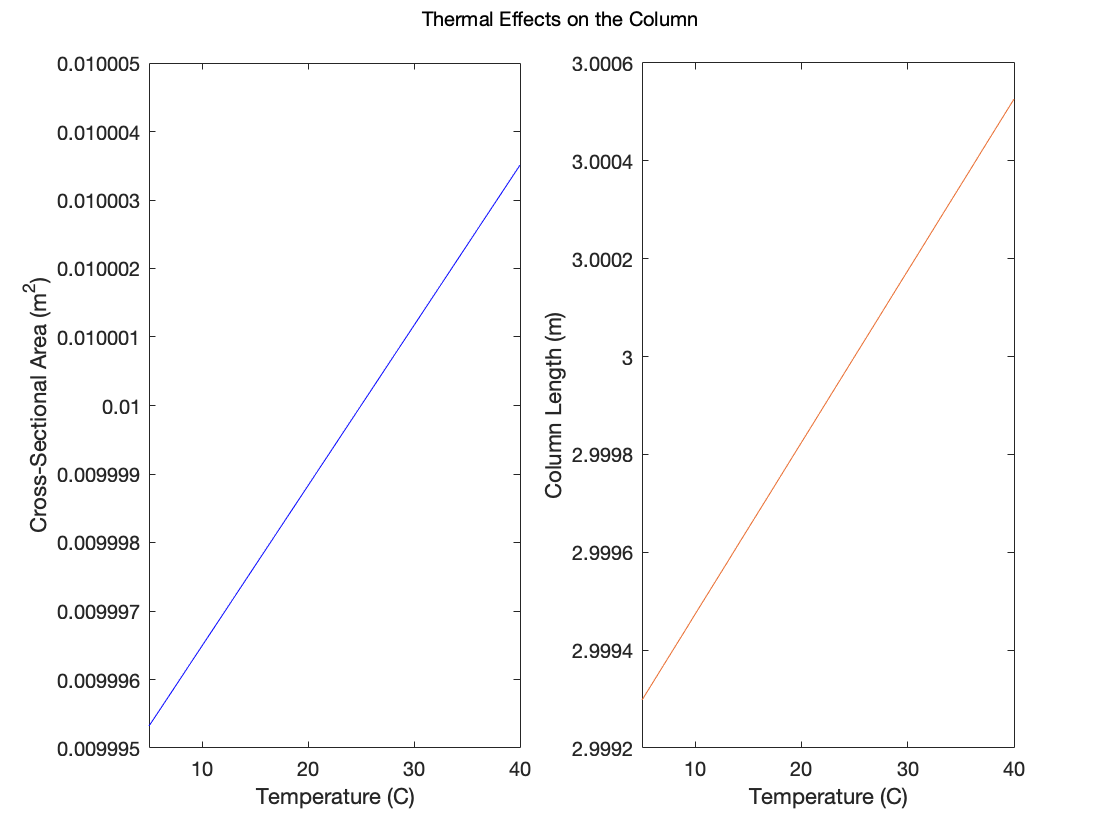

figure
%yyaxis left
subplot(1,2,1)
plot([buckling_initial.Temp], [buckling_initial.X].*[buckling_initial.Y], 'b-')
annotation('textbox', [0 0.9 1 0.1], ...
    'String', 'Thermal Effects on the Column', ...
    'EdgeColor', 'none', ...
    'HorizontalAlignment', 'center')
xlabel('Temperature (C)')
ylabel('Cross-Sectional Area (m^2)')
axis([5 40 9.995*10^(-3) 10.005*10^(-3)])
%yyaxis right
subplot(1,2,2)
plot([buckling_initial.Temp], [buckling_initial.Z], '-', 'Color', [0.91 0.41 0.17])
xlabel('Temperature (C)')
ylabel('Column Length (m)')
axis([5 40 2.9992 3.0006])

The dliemna here is that we can see that critical load will increase with increasing cross-sectional area, but it will decrease with increasing length. We therefore must analyze the critical load for all scenarios and plot to visually understand the optimal axially-loaded column dimensions for the design.

% Gate Thermal Analysis

## Buckling Analysis

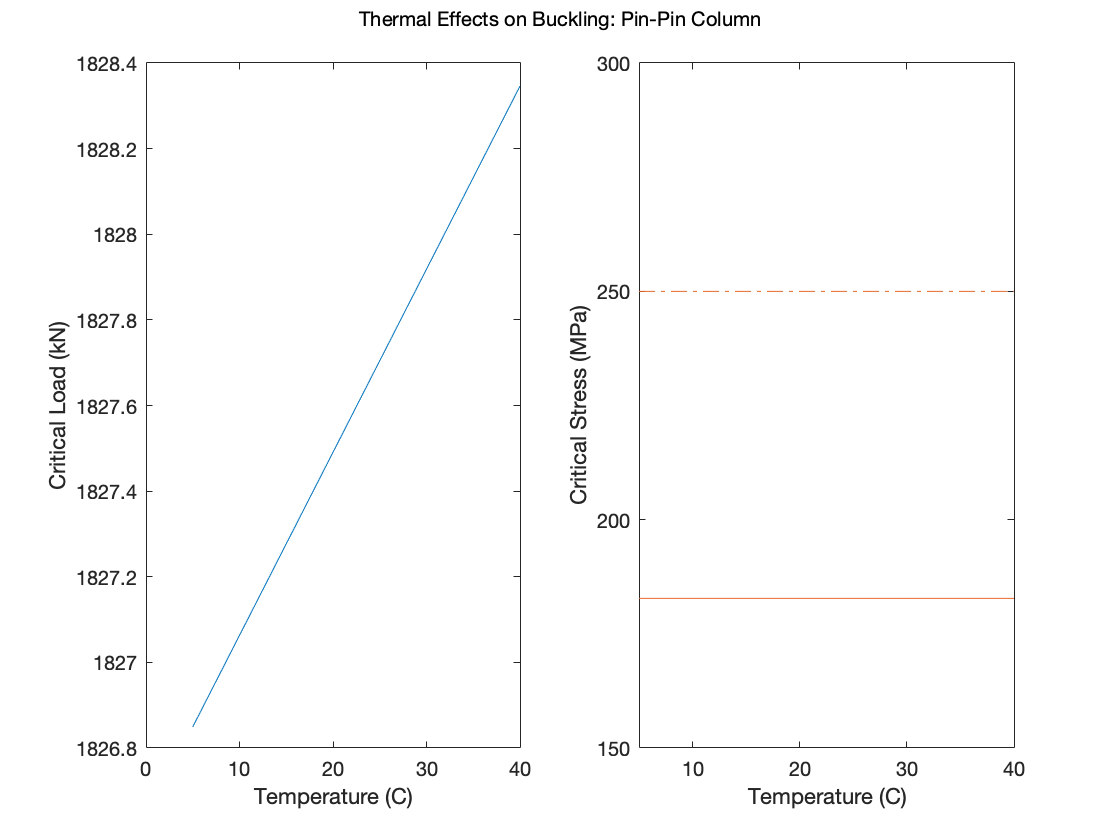

% Plot initial conditions for buckling - safety factor of 2

figure
%yyaxis left
subplot(1,2,1)
plot([buckling_initial.Temp], [buckling_initial.Crit_Load])
annotation('textbox', [0 0.9 1 0.1], ...
    'String', 'Thermal Effects on Buckling: Pin-Pin Column', ...
    'EdgeColor', 'none', ...
    'HorizontalAlignment', 'center')
xlabel('Temperature (C)')
ylabel('Critical Load (kN)')
%yyaxis right
subplot(1,2,2)
plot([buckling_initial.Temp], [buckling_initial.Crit_Stress], '-', 'color', [0.91 0.41 0.17])
xlabel('Temperature (C)')
ylabel('Critical Stress (MPa)')
hold on
plot([buckling_initial.Temp], (ones(1,length(temp)).*sigma_y)./(10^6), '-.', 'color', [0.91 0.41 0.17])
axis([5 40 150 300])
%legend('Critical Loading', 'Critical Stress', 'Yielding Stress', 'Location', 'northwest')
hold off

After several trials of different k-values, in order for this column to buckle before yielding (which we want), the k-value must be 1.0. This means it is a pin-pin supported column. There is no other way for the column to be supported (several trials were run for the various k-value that were commented in and out). We always want the critical stress to be less than the yielding stress throughout all temperatures.

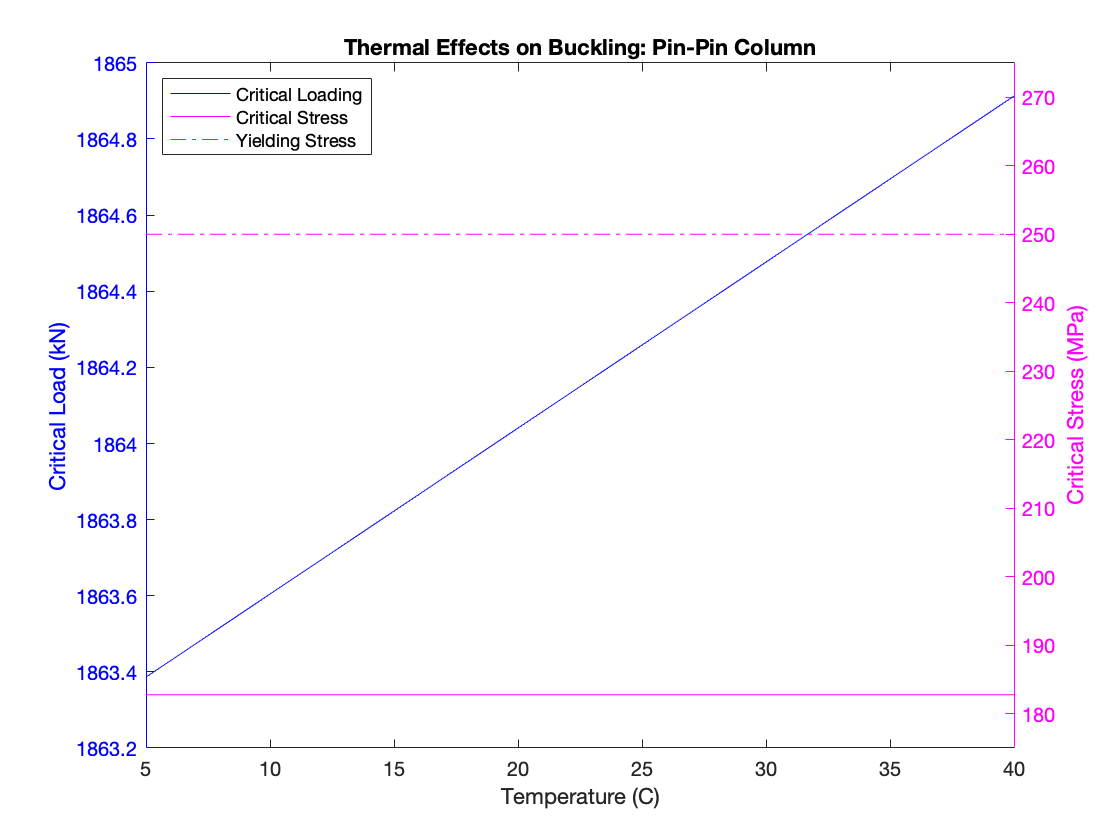

% Find final conditions for buckling
% Column Dimensions - Final
column_final(temp(end)-temp(1)+1) = struct('Temp', 0, 'X', 0, 'Y', 0, 'Z', 0, 'Crit_Load', 0, 'Crit_Stress', 0, 'Max_All_Load', 0);
for i = length(temp):-1:1
    column_final(i).Temp = temp(i);
    column_final(i).X = thermal_exp(alpha, (temp(i)-temp_i), (col_x+2*col_t)) + (col_x+2*col_t);
    column_final(i).Y = thermal_exp(alpha, (temp(i)-temp_i), col_y) + col_y;
    column_final(i).Z = thermal_exp(alpha, (temp(i)-temp_i), col_z) + col_z;
    [column_final(i).Crit_Load, column_final(i).Crit_Stress, column_final(i).Max_All_Load] = calc_buckling(column_final(i).X, ...
        column_final(i).Y, column_final(i).Z, E, k, 2);
end

figure
colororder({'b','m'})
yyaxis left
plot([column_final.Temp], [column_final.Crit_Load])
title('Thermal Effects on Buckling: Pin-Pin Column')
xlabel('Temperature (C)')
ylabel('Critical Load (kN)')
yyaxis right
plot([column_final.Temp], [column_final.Crit_Stress])
ylabel('Critical Stress (MPa)')
hold on
plot([column_final.Temp], (ones(1,length(temp)).*sigma_y)./(10^6), '-.')
axis([5 40 175 275])
legend('Critical Loading', 'Critical Stress', 'Yielding Stress', 'Location', 'northwest')
hold off

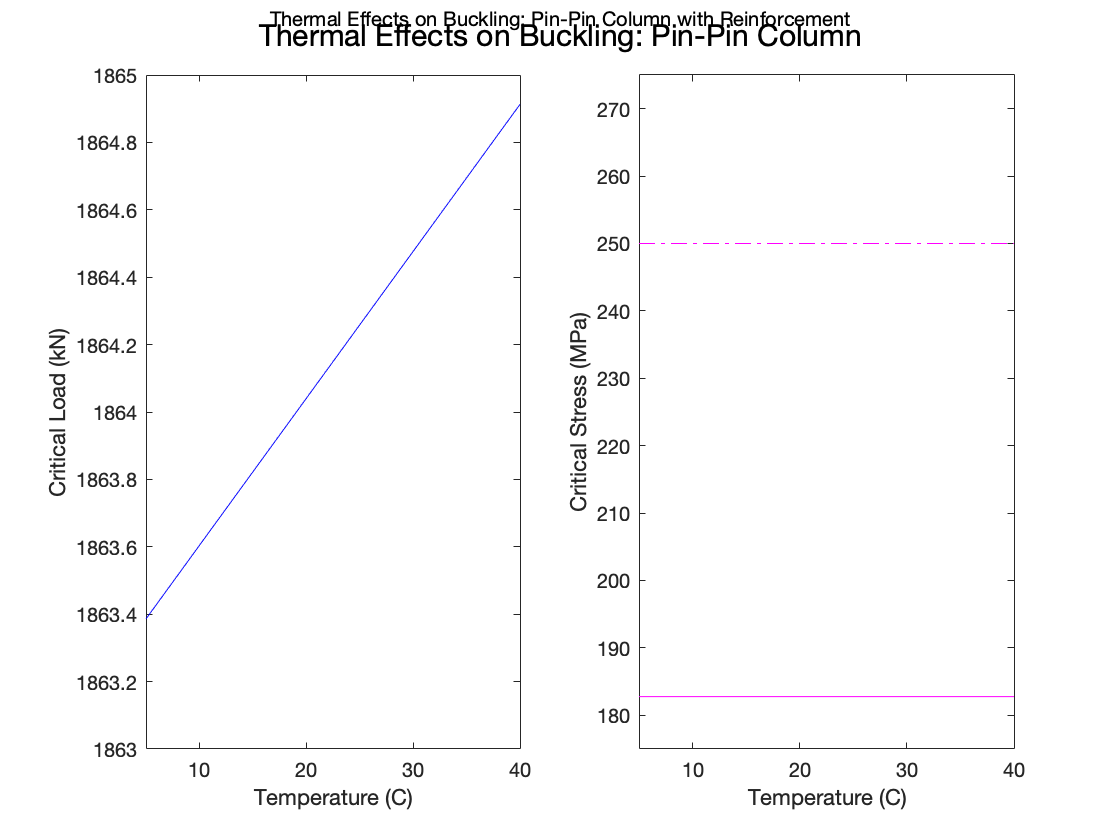

figure
subplot(1,2,1)
plot([column_final.Temp], [column_final.Crit_Load], 'b-')
annotation('textbox', [0 0.9 1 0.1], ...
    'String', 'Thermal Effects on Buckling: Pin-Pin Column with Reinforcement', ...
    'EdgeColor', 'none', ...
    'HorizontalAlignment', 'center')
sgtitle('Thermal Effects on Buckling: Pin-Pin Column')
xlabel('Temperature (C)')
ylabel('Critical Load (kN)')
axis([5 40 1863 1865])
subplot(1,2,2)
plot([column_final.Temp], [column_final.Crit_Stress], 'm-')
xlabel('Temperature (C)')
ylabel('Critical Stress (MPa)')
hold on
plot([column_final.Temp], (ones(1,length(temp)).*sigma_y)./(10^6), 'm-.')
axis([5 40 175 275])
hold off

column_final

column_final = 1×36 struct array with fields:
    Temp
    X
    Y
    Z
    Crit_Load
    Crit_Stress
    Max_All_Load


## Bending Analysis

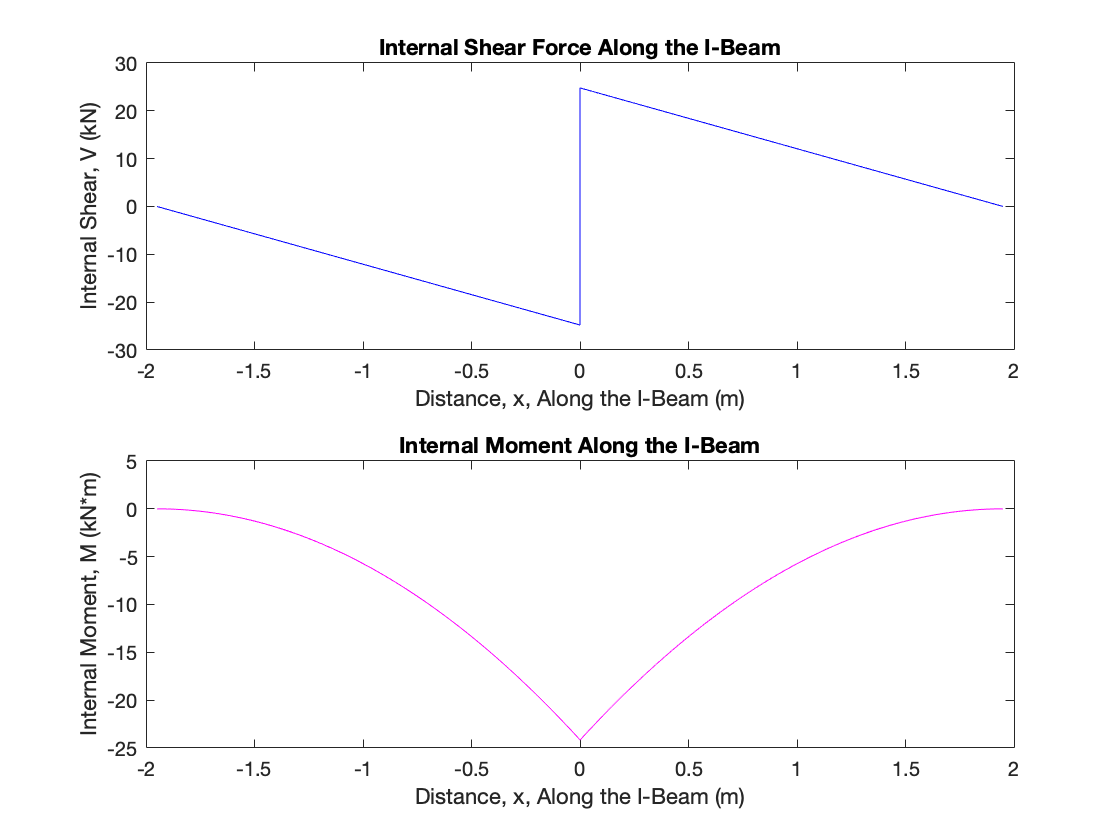

% Find I-beam with smallest cross-sectional area
small = find([ibeam_df.Area] == min([ibeam_df.Area]));
x_units = 0:0.001:(gate_x/2-col_x/2-col_t);
figure
subplot(2,1,1)
plot([x_units(end:-1:1).*(-1)], (-12.71376.*x_units), 'b-')
title('Internal Shear Force Along the I-Beam')
xlabel('Distance, x, Along the I-Beam (m)')
ylabel('Internal Shear, V (kN)')
hold on
plot(x_units, (24.792-12.71376.*x_units), 'b-')
hold on
plot(zeros(1,100), linspace(-24.792,24.792,100), 'b-')
hold off
subplot(2,1,2)
plot([x_units(end:-1:1).*(-1)], (-(12.71376/2).*(x_units.^2)), 'm-')
title('Internal Moment Along the I-Beam')
xlabel('Distance, x, Along the I-Beam (m)')
ylabel('Internal Moment, M (kN*m)')
hold on
plot(x_units, (-(12.71376/2).*(x_units.^2)+24.792.*x_units-24.172), 'm-')
hold off

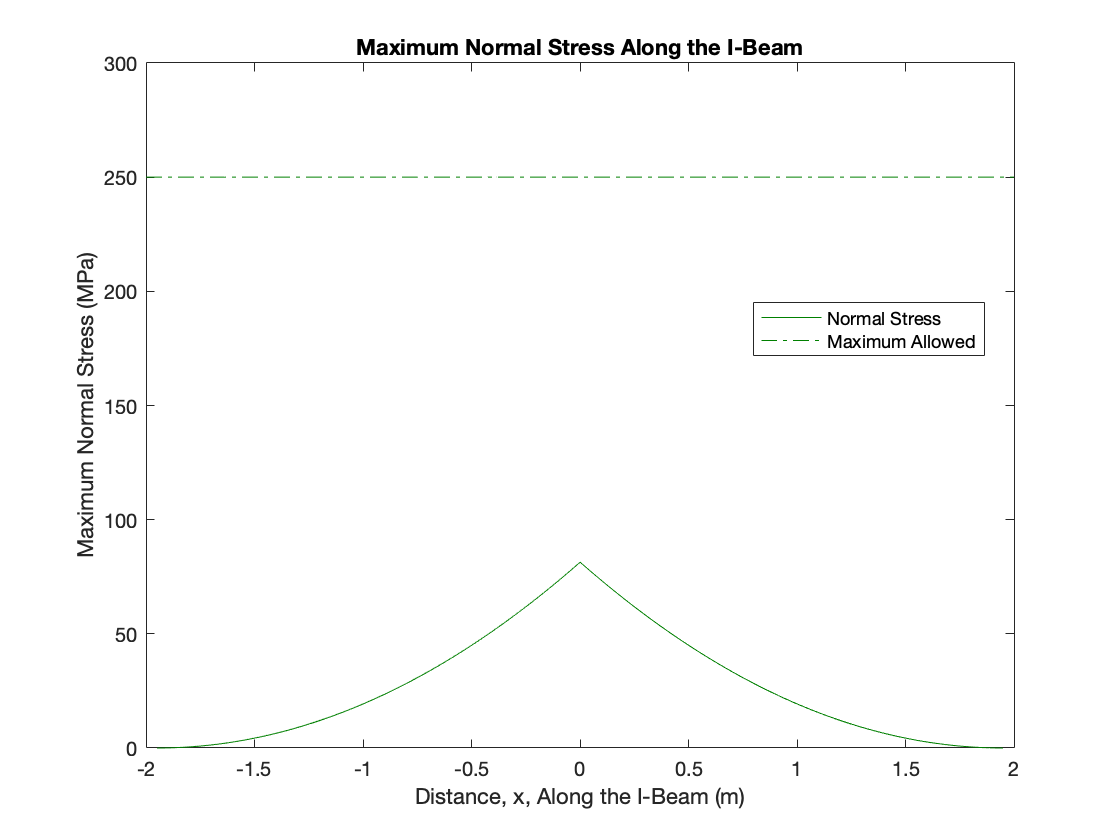

% Calculate Flexure
% Find Neutral Axis
NA_IBeam = calc_NA(ibeam_df(small).FThick, ibeam_df(small).WThick, ibeam_df(small).Depth, ibeam_df(small).FWidth, gate_z);
c_val = NA_IBeam;
if (ibeam_df(small).Depth - NA_IBeam) > NA_IBeam
    c_val = (ibeam_df(small).Depth - NA_IBeam);
end

M_val = [abs(-(12.71376/2).*(x_units.^2)) abs(-(12.71376/2).*(x_units.^2)+24.792.*x_units-24.172)];
sigma_max = (max_norm_stress(M_val, c_val, ibeam_df(small).I_final))./1000; % To get Mega Pascals
figure
plot([x_units(end:-1:1).*(-1) x_units], sigma_max, '-', 'Color', [0 0.5 0])
title('Maximum Normal Stress Along the I-Beam')
xlabel('Distance, x, Along the I-Beam (m)')
ylabel('Maximum Normal Stress (MPa)')
axis([-2 2 0 300])
hold on 
plot(linspace(-2,2,100), ones(1,100).*250, '-.', 'Color', [0 0.5 0])
legend('Normal Stress', 'Maximum Allowed', 'Location',"best")
hold off

max(sigma_max)

ans = 81.4316

The maximum normal stress found along the I-Beam is 81.43 MPa which is well below the maximum allowed of 250 MPa. Therefore, this I-Beam is still a wise choice.

## Deflection Analysis

% Calculate deflection of Smallest I-Beam
def_ibeam = zeros(1,200);
x_def = linspace(0,(gate_x/2-col_x/2-col_t), 200);
for i = 1:length(def_ibeam)
    def_ibeam(i) = calc_deflect(24792, E, ibeam_df(small).I_final, (gate_x/2-col_x/2-col_t), x_def(i))/1000; % Make into mm
end
max(abs(def_ibeam))

ans = 8.5104e-07


% Calculate deflection of gate without support of I-Beam
def_gate = zeros(1, 200);
for i = 1:length(def_gate)
    def_gate(i) = calc_deflect(7651.8, E, (1.041667*10^(-6)), (gate_x/2-col_x/2-col_t), x_def(i))/1000;
end
max(abs(def_gate))

ans = 7.4567e-06

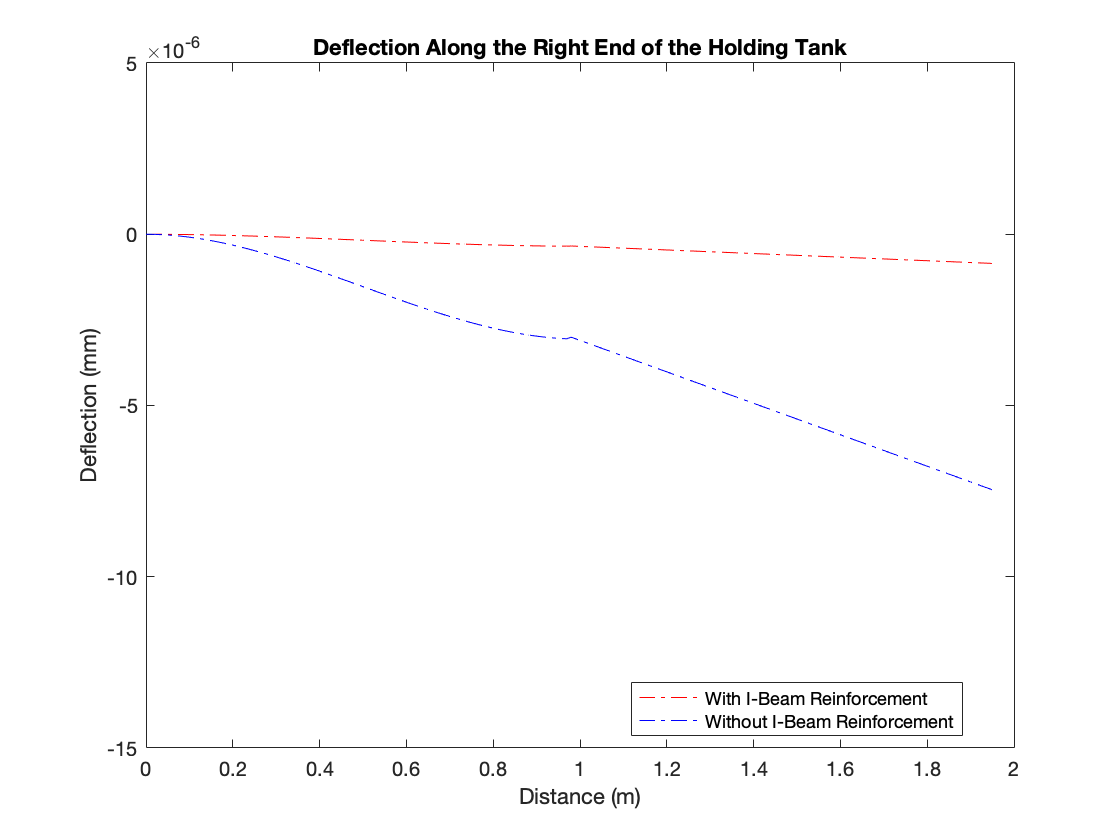

figure
plot(x_def, def_ibeam, 'r-.')
xlabel('Distance (m)')
ylabel('Deflection (mm)')
title('Deflection Along the Right End of the Holding Tank')
hold on
plot(x_def, def_gate, 'b-.')
axis([0 2 (-15*10^(-6)) (5*10^(-6))])
legend('With I-Beam Reinforcement', 'Without I-Beam Reinforcement', 'Location',"best")
hold off

## Transverse Shear Analysis

% On the I-beam at 25 degC
shear_vec = [];
for i = 1:row
    shear_vec(i) = shear_stress_ibeam(ibeam_df(i).FThick, ibeam_df(i).WThick, ibeam_df(i).Depth, ibeam_df(i).FWidth, gate_z);
end
max(shear_vec)

ans = 8.8184e+03

shear_vec(small)

ans = 7.5226e+03

NA_IBeam

NA_IBeam = 0.0504

Based on the shear analysis, the maximum shear stress that will be experienced by any of the I-Beams in the structure is only 8.818 kPa, which is much less than the 150MPa limit. 

Therefore, any of the I-Beams will suffice for holding the water. Also, since the thermal effects will be so small in comparison, we can assume that they're negligible here.

Since the goal is to control for cost and assuming that cost is directly proportional to I-Beam size, choose the I-Beam with the smallest cross-sectional area based on max shear.

function out = calc_Ivalue(tf, tw, d, bf, th)
% Returns moment of inertia of cross section about neutral axis based on
% reinforcing of gate of certain thickness, measuring from top
% Format of the call: calc_Ivalue()
A1 = bf.*(tf+th);
Z1 = (tf+th)./2;
A2 = tw.*(d-2.*tf);
Z2 = th+tf+(d-2.*tf)./2;
A3 = bf.*tf;
Z3 = th + tf + (d-2.*tf) + (tf./2);
NA = (A1.*Z1 + A2.*Z2 + A3.*Z3)./(A1 + A2 + A3);
I_1 = (1/12).*bf.*((tf+th).^3) + bf.*(tf+th).*((NA - (th+tf)./2).^2);
I_2 = (1/12).*tw.*((d-2.*tf).^3) + tw.*(d-2.*tf).*(th+tf+(d-2.*tf)-NA).^2;
I_3 = (1/12).*bf.*(tf.^3) + bf.*tf.*(th+(d-2.*tf)+(3/2).*tf-NA).^2;
out = I_1 + I_2 + I_3;
end

function out = calc_NA(tf, tw, d, bf, th)
A1 = bf.*(tf+th);
Z1 = (tf+th)./2;
A2 = tw.*(d-2.*tf);
Z2 = th+tf+(d-2.*tf)./2;
A3 = bf.*tf;
Z3 = th + tf + (d-2.*tf) + (tf./2);
out = (A1.*Z1 + A2.*Z2 + A3.*Z3)./(A1 + A2 + A3);
end

function out = thermal_exp(alpha, delT, len)
% Returns thermal expansion in meters of a material
% Format of the call: thermal_exp(alpha_co, deltaT, length)
out = alpha.*delT.*len;
end

function [P_cr, Sig_cr, P_all] = calc_buckling(dimx, dimy, dimz, YM, k_col, SF)
% Returns column's critical load (kN), critical stress (MPa), and max
% allowable load (kN)
% Format of the call: calc_buckling(cross-section dimension1, cross-section 
% dimension2, length of column, young's modulus, k coefficient, safety factor)
A = dimx.*dimy;
I1 = (1/12).*dimx.*(dimy).^3;
I2 = (1/12).*dimy.*(dimx).^3;
if I1 > I2 % Must use smallest I
    I = I2;
else
    I = I1;
end
P_cr = ((pi^2.*YM.*I)./(k_col.*dimz).^2)./1000;
r = (I./A).^(1/2);
Sig_cr = ((pi^2.*YM)./((k_col.*dimz./r).^2))./(10^6);
P_all = P_cr./SF;
end

function out = max_norm_stress(M, c, I)
out = M.*c./I;
end

function out = weight(dim1, dim2, dim3, rho)
% Returns the weight force in kN based on volume and density
% Format of the call: weight(dimension1, dimension2, dimension3,
% density)
out = dim1.*dim2.*dim3.*rho.*9.81./1000;
end

function out = shear_stress_ibeam(tf, tw, d, bf, th)
% Returns the maximum shear of the IBeam
% Format of the call: shear_stress_ibeam()
A1 = bf.*(tf+th);
Z1 = (tf+th)./2;
A2 = tw.*(d-2.*tf);
Z2 = th+tf+(d-2.*tf)./2;
A3 = bf.*tf;
Z3 = th + tf + (d-2.*tf) + (tf./2);
NA = (A1.*Z1 + A2.*Z2 + A3.*Z3)./(A1 + A2 + A3);
I_1 = (1/12).*bf.*((tf+th).^3) + bf.*(tf+th).*((NA - (th+tf)./2).^2);
I_2 = (1/12).*tw.*((d-2.*tf).^3) + tw.*(d-2.*tf).*(th+tf+(d-2.*tf)-NA).^2;
I_3 = (1/12).*bf.*(tf.^3) + bf.*tf.*(th+(d-2.*tf)+(3/2).*tf-NA).^2;
Itot = I_1 + I_2 + I_3;
V = 1000*1.95*4*(bf/1000)*9.81; % Based on water density and dimensions of I-beam (no column)
Q = (NA - (tf+th)./2).*((tf+th).*bf)+(NA - (NA-tf-th)./2).*((NA-th-tf)./2).*(NA-tf-th).*(tw);
out = V.*Q./(Itot.*tw); % Max Shear 
end

function out = calc_deflect(F, YM, MI, L, x)
% Calculates the deflection of cantilever with free end on right
if x < (L/2)
    constant = F/(12*YM*MI);
    eq = (2.*x.^3) - (3.*x.^2);
else
    constant = F/(48*YM*MI);
    eq = -6.*x + L;
end
out = constant*eq;
end













